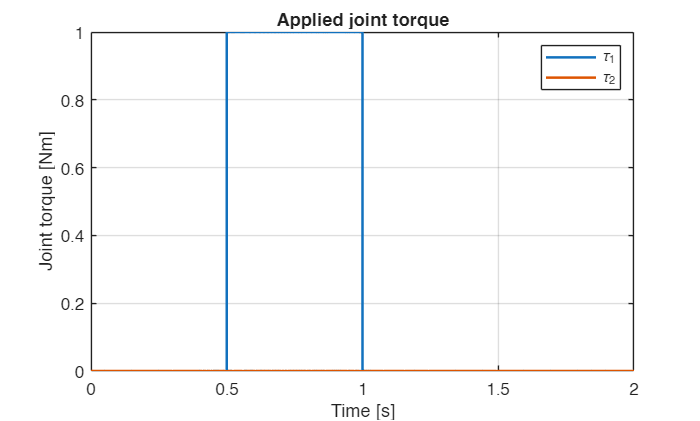

clear;
close all;
clc;

param = robot_parameters();

%% Initial state
q0 = [
    deg2rad(120);
    deg2rad(60)
];

dq0 = [
    0;
    0
];

x0 = [
    q0;
    dq0
];

%% Simulation time
tspan = [0, 2.0];

%% ODE solution
options = odeset( ...
    'RelTol', 1e-8, ...
    'AbsTol', 1e-10);

[t, x] = ode45( ...
    @(t, x) forward_dynamics_M_only(t, x, param), ...
    tspan, ...
    x0, ...
    options);

%% Extract states
q  = x(:, 1:2);
dq = x(:, 3:4);

%% Recalculate acceleration and torque
N = length(t);

ddq = zeros(N, 2);
tau = zeros(N, 2);

for k = 1:N

    qk = q(k, :).';

    M = mass_matrix(qk, param);

    if t(k) >= 0.5 && t(k) < 1.0
        tau_k = [
            1.0;
            0.0
        ];
    else
        tau_k = [
            0.0;
            0.0
        ];
    end

    ddq_k = M \ tau_k;

    tau(k, :) = tau_k.';
    ddq(k, :) = ddq_k.';

end

%% Plot joint torque
figure;

plot(t, tau(:, 1), 'LineWidth', 1.5);
hold on;
plot(t, tau(:, 2), 'LineWidth', 1.5);

grid on;
xlabel('Time [s]');
ylabel('Joint torque [Nm]');
legend('\tau_1', '\tau_2');
title('Applied joint torque');

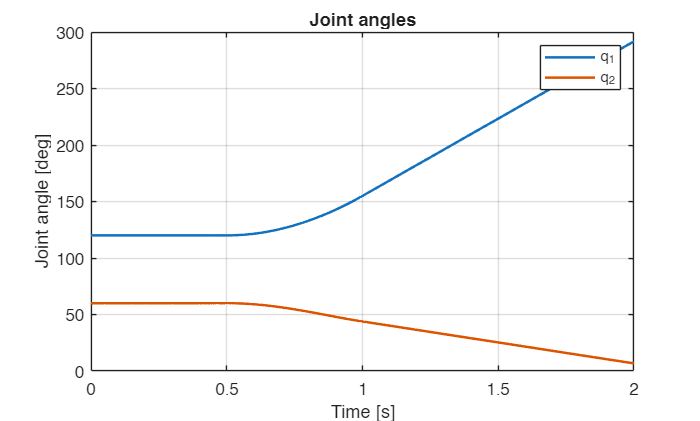


%% Plot joint angle
figure;

plot(t, rad2deg(q(:, 1)), 'LineWidth', 1.5);
hold on;
plot(t, rad2deg(q(:, 2)), 'LineWidth', 1.5);

grid on;
xlabel('Time [s]');
ylabel('Joint angle [deg]');
legend('q_1', 'q_2');
title('Joint angles');

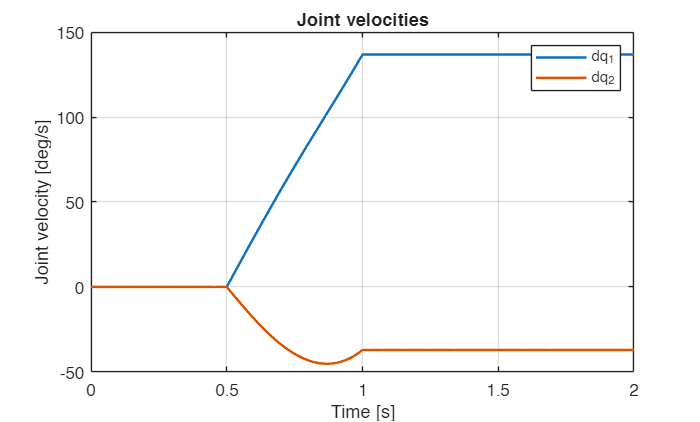


%% Plot joint velocity
figure;

plot(t, rad2deg(dq(:, 1)), 'LineWidth', 1.5);
hold on;
plot(t, rad2deg(dq(:, 2)), 'LineWidth', 1.5);

grid on;
xlabel('Time [s]');
ylabel('Joint velocity [deg/s]');
legend('dq_1', 'dq_2');
title('Joint velocities');

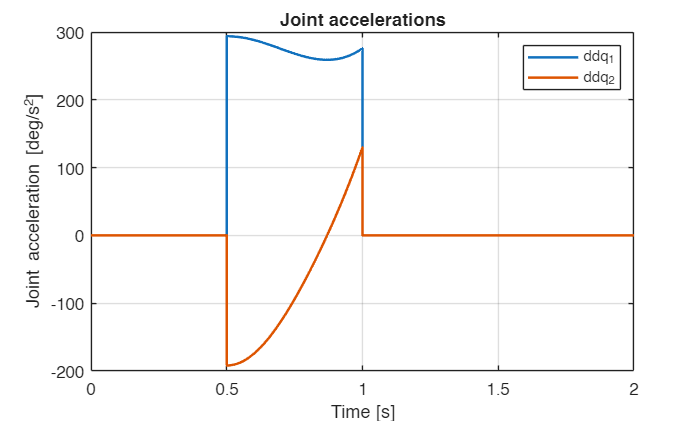


%% Plot joint acceleration
figure;

plot(t, rad2deg(ddq(:, 1)), 'LineWidth', 1.5);
hold on;
plot(t, rad2deg(ddq(:, 2)), 'LineWidth', 1.5);

grid on;
xlabel('Time [s]');
ylabel('Joint acceleration [deg/s^2]');
legend('ddq_1', 'ddq_2');
title('Joint accelerations');